# Best path

Template for best part solution in directed graph

#### Create random graph with desired nodes amount

na =9;

s = randi(na, na * 3, 1);
t = randi(na, na * 3, 1);

g = digraph(s, t, s, 'omitselfloops');


#### Set graph's edges width

g.Edges.LWidths = 4 * g.Edges.Weight / max(g.Edges.Weight);
g.Nodes.NodeColors = indegree(g);


#### Plot graph and make some decor


p = plot(g,'EdgeLabel', g.Edges.Weight);
p.NodeCData = g.Nodes.NodeColors;
p.MarkerSize = 7;
p.ArrowSize = 12;
p.EdgeColor = [0.5 0.5 0.5];
p.LineWidth = g.Edges.LWidths;


#### Select two nodes randomly and find best path fron begin to end

rng();
b = randi(na, 1);
e = randsample(setdiff(1:na, b), 1);
sp = shortestpath(g, b, e);


#### Highlight path on the graph

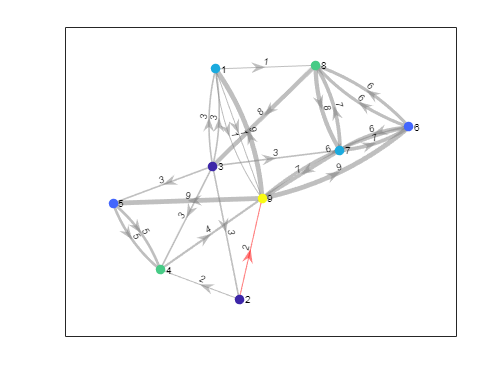

p.EdgeColor = [0.5 0.5 0.5];
highlight(p, sp,'EdgeColor', [1 0 0]);